# Red neuronal

clear all;

load datosOT.mat
load datosZC.mat

varName = ["d1","d2","d3","d4","d5","d6","d7","d8","d9","d10",...
    "d11","d12","d13","d14","d15","d16","d17","d18","d19","d20",...
    "d21","d22","d23"];

[totZC,~] = size(datosZC); 
[totOT,~] = size(datosOT);

tentreZC = 15;
tentreOT = 80;

datos = [datosZC(1:tentreZC,:); datosOT(1:tentreOT,:)];
prueba = [datosZC(tentreZC+1:end,:); datosOT(tentreOT+1:end,:)];

tipoDatos = [tipoZC(1:tentreZC); tipoOT(1:tentreOT)];
tipoPrueba = [tipoZC(tentreZC+1:end); tipoOT(tentreOT+1:end)];

test1 = datos(10,:);
test2 = datos(87,:);


datos = array2table(datos,VariableNames=varName);
datos.tipo = tipoDatos;

prueba = array2table(prueba,"VariableNames",varName);
prueba.tipo = tipoPrueba;



%A
% knnmodel = fitcknn(datos,"tipo", ...
%     "NumNeighbors",5, ...
%     "Standardize",true, ...
%     "DistanceWeight","squaredinverse");

%B
knnmodel = fitcknn(datos,"tipo",...
    'Distance', 'Euclidean', ...
    'NumNeighbors', 10, ...
    'DistanceWeight', 'Equal', ...
    'Standardize', true);

clasificacion = predict(knnmodel,datos)

clasificacion =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


isincorrect = clasificacion ~= datos.tipo

isincorrect = 95×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


misclassrate = sum(isincorrect)/numel(isincorrect)

misclassrate =    0.010526315789474


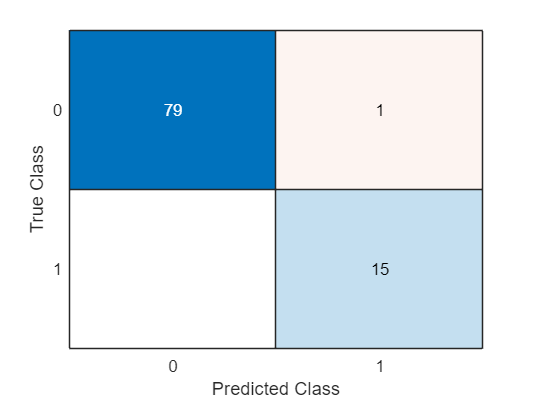

confusionchart(datos.tipo,clasificacion);


clasificacion = predict(knnmodel,prueba)

clasificacion =      1
     1
     1
     1
     1
     0
     1
     1
     1
     0


isincorrect = clasificacion ~= prueba.tipo

isincorrect = 96×1 logical array
   0
   0
   0
   0
   0
   1
   0
   0
   0
   1


misclassrate = sum(isincorrect)/numel(isincorrect)

misclassrate =    0.062500000000000


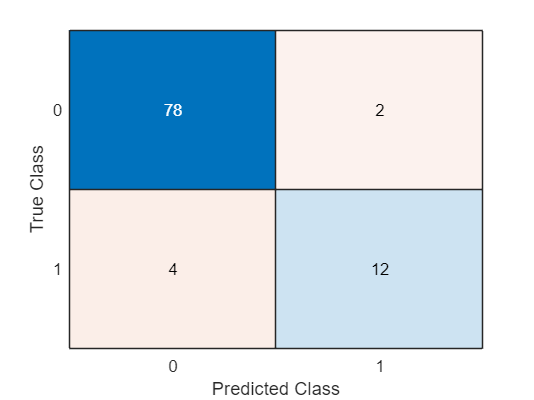

confusionchart(prueba.tipo,clasificacion);

clase = predict(knnmodel ,test1)

clase =      1


clase = predict(knnmodel,test2)

clase =      0


%usar red neuronal

test1t = array2table(test1,VariableNames=varName)

test1t = 1×23 table
           d1                   d2                   d3                  d4                   d5                   d6             d7             d8                   d9                   d10                  d11                  d12                  d13                  d14                  d15                  d16                  d17                  d18                  d19                  d20                  d21                  d22                  d23       
    _________________    _________________    ________________    <

test2t = array2table(test2,VariableNames=varName)

test2t = 1×23 table
           d1                   d2                   d3                   d4                   d5                   d6                   d7                   d8                  d9             d10             d11                  d12                  d13                  d14                  d15                  d16                  d17                  d18                  d19                  d20                  d21                  d22                  d23       
    _________________    _________________    _________________   


clase = trainedModel.predictFcn(test1t)

clase =      1


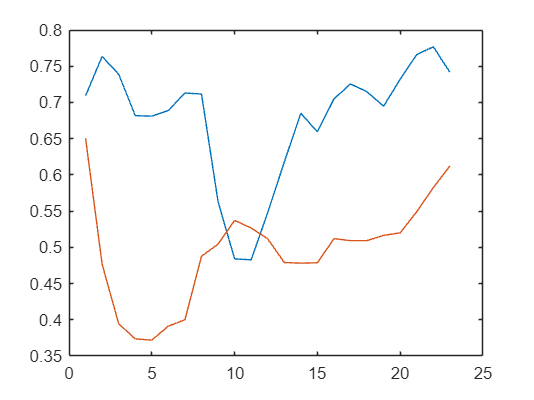

figure;
plot(test1)
hold on
plot(test2)
hold off

clase = trainedModel.predictFcn(test2t)

clase =      0
